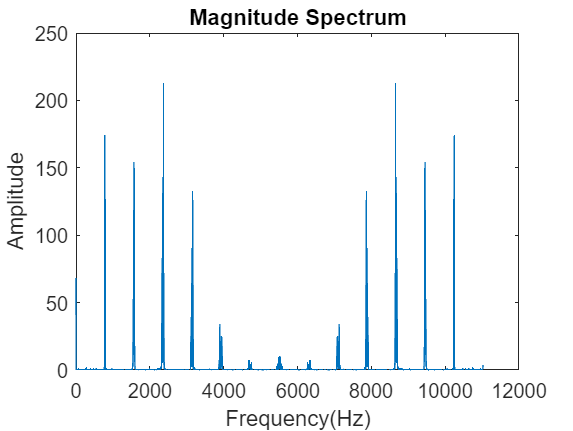

[x,Fs] = audioread("instru2.wav");
m = abs(fft(x));
F = (0:length(m)-1)*Fs/length(m);
figure(1)
plot(F,m)
title('Magnitude Spectrum')
xlabel("Frequency(Hz)");
ylabel("Amplitude");

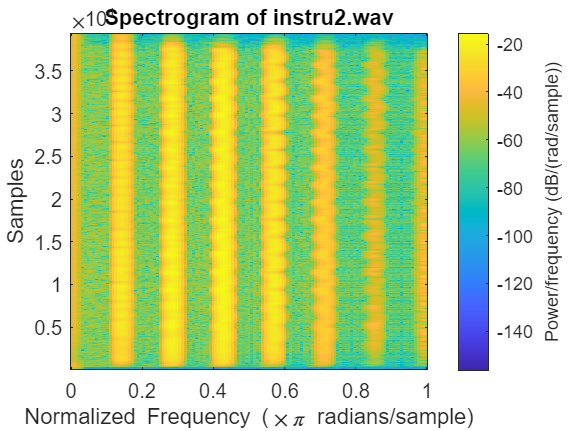


% Spectrogram parameters
window_length = 100; % Length of the Hamming window (samples)
overlap = 10;        % Overlap between consecutive windows (samples)
window_length_2 = 150;

% Create and plot the spectrogram
figure(2);
spectrogram(x, hamming(window_length), overlap);
title('Spectrogram of instru2.wav');

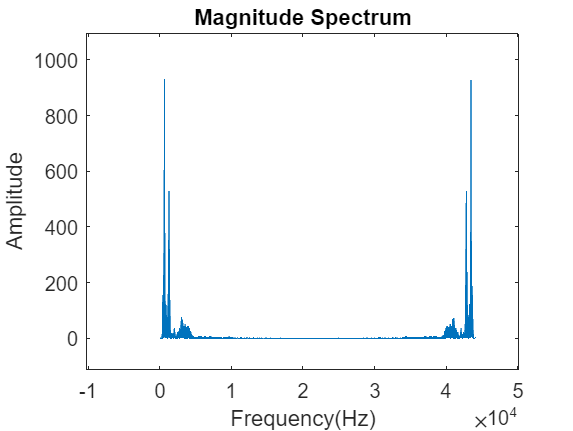



[x1,Fs1] = audioread("opera.wav");
m1 = abs(fft(x1));
F1 = (0:length(m1)-1)*Fs1/length(m1);
figure(3)
plot(F1,m1)
title('Magnitude Spectrum')
xlabel("Frequency(Hz)");
ylabel("Amplitude");

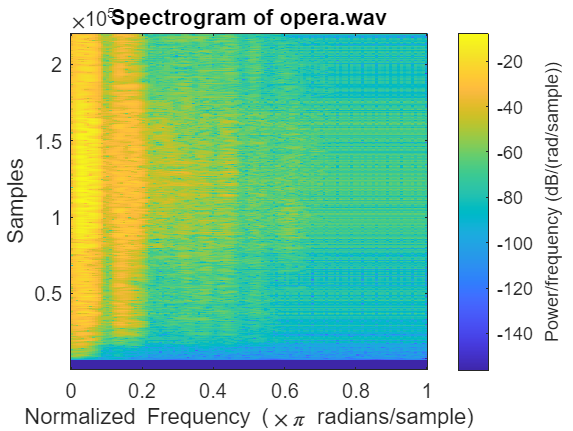


% Spectrogram parameters
window_length = 100; % Length of the Hamming window (samples)
overlap = 10;        % Overlap between consecutive windows (samples)

% Create and plot the spectrogram
figure(4);
spectrogram(x1, hamming(window_length), overlap);
title('Spectrogram of opera.wav');

%}